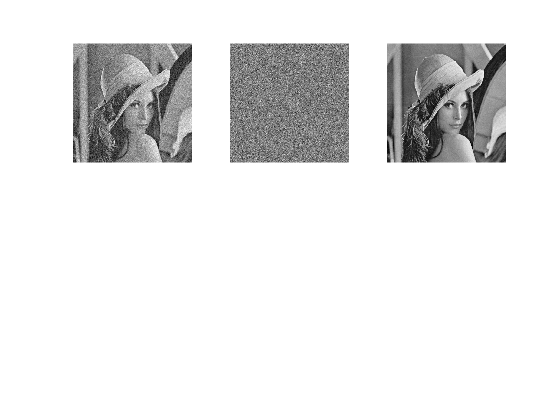

listdir = dir('./LenaPics/*.jpg');

n = size(listdir);
mI = zeros(512,512);

for x = 1:n
    path = sprintf('./LenaPics/%s', listdir(x).name);
    mI(:, :, x) = imread(path);
    mI = double(mI);
end

mI_avg = mean(mI, 3);
figure,
subplot(231), imshow(mI(:, :, 1), [])
subplot(233), imshow(mI_avg, [])

mI_diff = mI(:, :, 1) - mI_avg(:, :);
%mI_diff = sqrt(mI_diff.^2);
subplot(232),imshow(mI_diff, [])


P_noise = std(mI_diff(:))^2

P_noise = 248.8630

P_mean = std(mI_avg(:))^2

P_mean = 1.8383e+03

P_org = std(mI(:))^2

P_org = 2.0867e+03

P = P_noise + P_mean

P = 2.0872e+03

SNR_db = 10*log(P_mean/P_noise)

SNR_db = 19.9971